# SNW_V_PLANNER Planner Value Small Test

This is the example vignette for function: [**snw_v_planner**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_v_planner.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**.** This solves the planner's problem with various checks. The planner considers unemployed and employed states and observes previous age, child count, marriage status and income level.

## Step 1: Set Parameters

Set checks and other key parameters:

% Set Parameters
mp_params = snw_mp_param('default_dense');
mp_params('n_welfchecksgrid') = 51;
n_incgrid = 5;
mp_params('n_incgrid') = n_incgrid;
mp_params('inc_grid') = linspace(0, 7, n_incgrid)'; % 7 refers to 7*58056=406392 dollars in 2012USD    

Set Controls:

mp_controls = snw_mp_control('default_test');
mp_controls('bl_timer') = true;
mp_controls('bl_print_ds') = false;
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_a4chk') = false;
mp_controls('bl_print_vu_vw') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_a4chk_verbose') = false;
mp_controls('bl_print_vu_vw_verbose') = false;
mp_controls('bl_print_v_planner') = true;
mp_controls('bl_print_v_planner_verbose') = false;

## Step 2: Solve the Checks Problem (Includes VFI)

% Solve At all Checks
st_solu_type = 'bisec_vec';
[~, ap_ss, cons_ss, ~, ~, ~, ...
    V_W_allchecks, C_W_allchecks, V_U_allchecks, C_U_allchecks] = snw_vu_vw_checks(st_solu_type, mp_params, mp_controls);

Elapsed time is 1.238061 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 1.145859 seconds.
Completed SNW_VFI_MAIN 1 PERIOD UNEMP SHK;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 0.085316 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=0;TR=0.0017225;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 0.081262 seconds.
Completed SNW_A4CHK_UNEMP_BISEC_VEC;welf_checks=0;TR=0.0017225;xi=0.75;b=1;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 0.076043 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=1;TR=0.0017225;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 0.077498 seconds.
Completed SNW_A4CHK_UNEMP_BISEC_VEC;welf_checks=1;TR=0.0017225;xi=0.75;b=1;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 0.075357 seconds.
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=2;TR=0.0017225;SNW_MP_PARAM=default_small;SNW_MP_

## Step 3: Solve for the Distribution

[Phi_true,~,~,~,~,~] = snw_ds_main(mp_params, mp_controls, ap_ss, cons_ss);

Elapsed time is 1.292895 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 2.878051 seconds.
Completed SNW_DS_MAIN;SNW_MP_PARAM=;default_small;SNW_MP_CONTROL=;default_test


## Step 4: Solve for Planner Value

% Solve the Planning Problem
[V_planner, C_planner, Phi_mass, output] ...
    = snw_v_planner(mp_params, mp_controls, ...
    Phi_true, ap_ss, V_W_allchecks, C_W_allchecks, V_U_allchecks, C_U_allchecks);

Wage quintile cutoffs=0.64264     0.88905      1.0754      1.5929
SNW_V_PLANNER: c(1) or v(2):1
SNW_V_PLANNER: Finished Age Group:1 of 17
SNW_V_PLANNER: Finished Age Group:2 of 17
SNW_V_PLANNER: Finished Age Group:3 of 17
SNW_V_PLANNER: Finished Age Group:4 of 17
SNW_V_PLANNER: Finished Age Group:5 of 17
SNW_V_PLANNER: Finished Age Group:6 of 17
SNW_V_PLANNER: Finished Age Group:7 of 17
SNW_V_PLANNER: Finished Age Group:8 of 17
SNW_V_PLANNER: Finished Age Group:9 of 17
SNW_V_PLANNER: Finished Age Group:10 of 17
SNW_V_PLANNER: Finished Age Group:11 of 17
SNW_V_PLANNER: Finished Age Group:12 of 17
SNW_V_PLANNER: Finished Age Group:13 of 17
SNW_V_PLANNER: Finished Age Group:14 of 17
SNW_V_PLANNER: Finished Age Group:15 of 17
SNW_V_PLANNER: Finished Age Group:16 of 17
SNW_V_PLANNER: Finished Age Group:17 of 17
SNW_V_PLANNER: c(1) or v(2):2
SNW_V_PLANNER: Finished Age Group:1 of 17
SNW_V_PLANNER: Finished Age Group:2 of 17
SNW_V_PLANNER: Finished Age Group:3 of 17
SNW_V_PLANNER: Finished Ag

## A. Distributional Mass Along Various Dimensions

*Phi_mass* has four dimensions: age, marriage status, kids, income groups

% Grids:
age_grid = [19, 22:5:97];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
inc_grid = mp_params('inc_grid')*58056;
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'kids', kids_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'ylower', inc_grid});

#### A1. Age, Marriage Status and Kids Count

These mass are the same as under ds_main analysis files, mass by age, marriage and kids count has not changed.

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [4,1,3,2];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_mass, true, ["sum"], 1, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97
    _____    ____    _____    __________    __________    __________    __________    __________    __________    __________    __________    ___

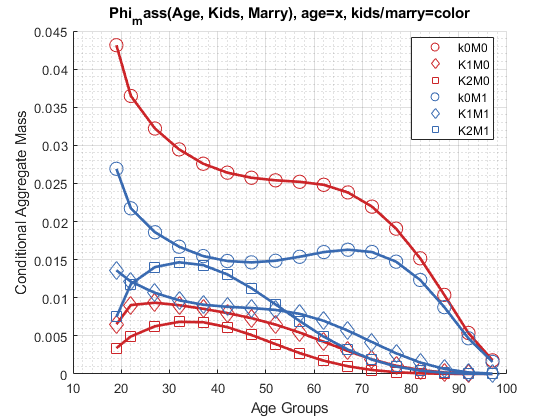

mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log
mp_support_graph('cl_st_graph_title') = {'Phi_mass(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);